# Training Unit 2: NEDC Simulation

Fink Lucas / Teichtmeister Marcus, 08.10.2025

## MATLAB Setup

clear
clc

LaTex-Interpreter als Standard für Grafiken setzen

set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Schriftgröße für Grafiken setzen

set(groot, 'defaultTextFontSize', 11)
set(groot, 'defaultAxesFontSize', 11)
set(groot, 'defaultLegendFontSize', 11)

Verzeichnis wechseln (in Verzeichnis des Live-Skripts)

cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Loading and processing of existing data

Storing the parameters of the vehicle under investigation

VEHICLE_PARAMETER.VEHICLE_WEIGHT.data        = struct('value', 1250, 'unit', 'kg');
VEHICLE_PARAMETER.E_MOTOR_POWER.data         = struct('value', 66,   'unit', 'kW');
VEHICLE_PARAMETER.BATTERY_CAPACITY.data      = struct('value', 22,   'unit', 'kWh');
VEHICLE_PARAMETER.TRANSMISSION_EFFIENCY.data = struct('value', 96,   'unit', '%');
VEHICLE_PARAMETER.ENGINE_EFFIENCY.data       = struct('value', 94,   'unit', '%');
VEHICLE_PARAMETER.INVERTER_EFFIENCY.data     = struct('value', 97,   'unit', '%');
VEHICLE_PARAMETER.BATTERY_EFFIENCY.data      = struct('value', 90,   'unit', '%');
VEHICLE_PARAMETER.CHARGER_EFFIENCY.data      = struct('value', 94,   'unit', '%');

Next, the collected data "MotorSpeed", "Distance" and "VehicleSpeed" will be read out from the Data.xls File. The data is merged into a table with 3 columns. This is handled by the MATLAB function "importExcelData" which gets the filename as a parameter and returns the extracted data table.

The displayed size of the table is: 2401x3

filename_data = 'Data.xls';
dataTable = importExcelData(filename_data)

dataTable = 2401×3 table
    MotorSpeed[rad/s]    Distance[m]    VehicleSpeed[km/h]
    _________________    ___________    __________________
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                

Furthermore, a second MATLAB function "importTorqueData" is implemented which stores the torque data in the already existing data table and also includes the sampling time as the first column in the table.

The object **Motor_Torque i**ncludes 2401 data points of motor torque values over time. The dataset provides both the torque data and the corresponding time vector, as well as additional metadata for time, data, and quality. The datapoints of the time vector suggests that the data was recorded with consistent sampling. The metadata also indicates that NaN values are treated as missing data.

filename_torque = 'Torque.mat';
dataTable = importTorqueData(filename_torque, dataTable)

dataTable = 2401×5 table
    sampling_time[s]    MotorSpeed[rad/s]    Distance[m]    VehicleSpeed[km/h]    Torque[Nm]
    ________________    _________________    ___________    __________________    __________
            0                   0                 0                 0                 0     
          0.5                   0                 0                 0                 0     
            1                   0                 0                 0                 0     
          1.5                   0                 0                 0                 0     
            2                   0                 0                 0                 0     
          2.5                   0                 0                 0                 0     
            3                   0                 0          

The imported torque time series and other artifacts are removed from the workspace.

clearvars -except dataTable VEHICLE_PARAMETER;

### Presenting the results

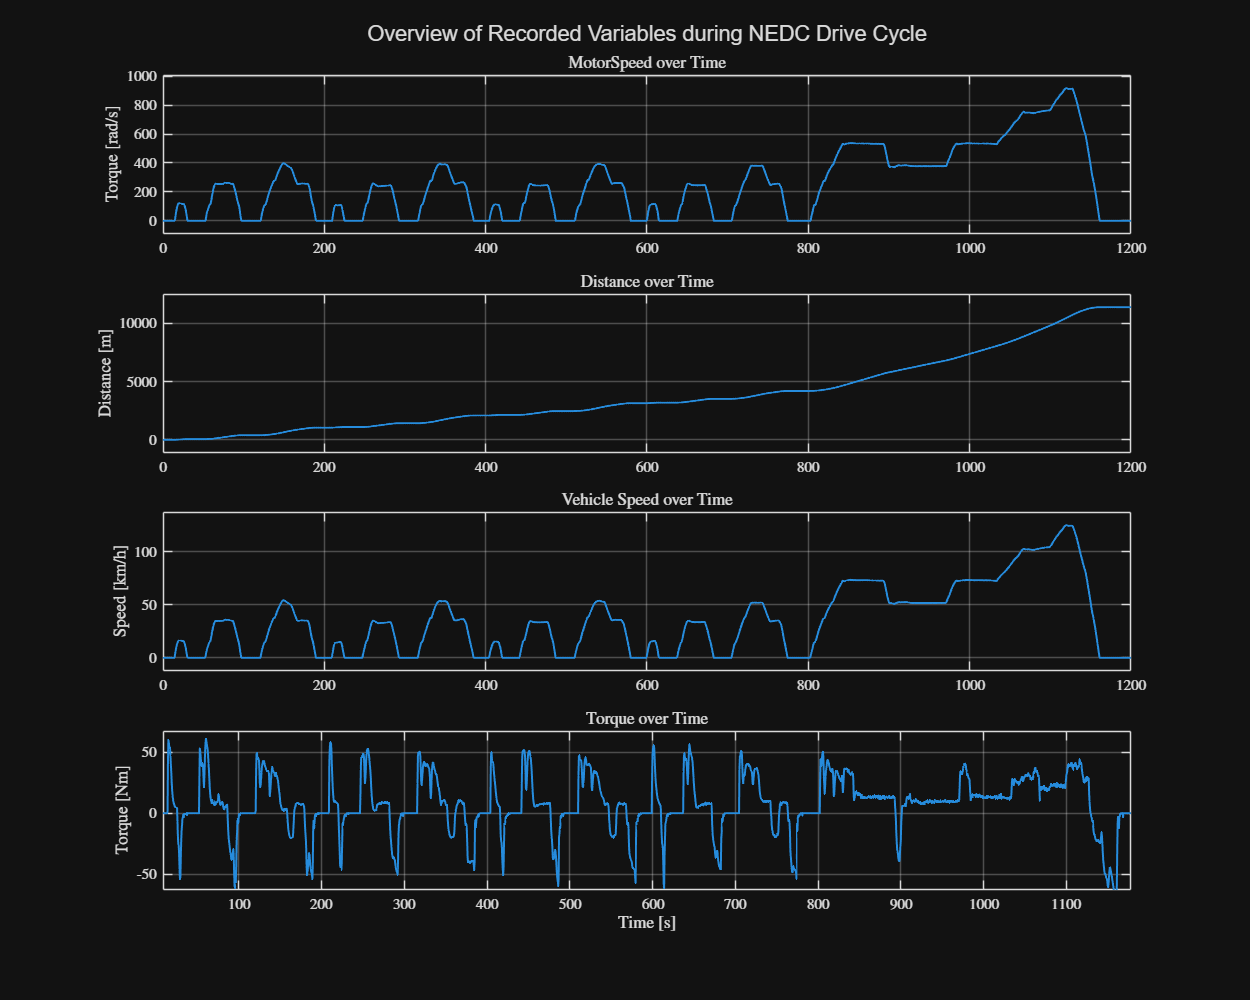

time = dataTable{:,1};              
motor_speed = dataTable{:,2};             
distance = dataTable{:,3};              
vehicle_speed = dataTable{:,4};             
torque = dataTable{:,5};              

figure('Position', [100, 100, 1000, 800])
tiledlayout(4, 1)    

% 1. Plot: MotorSpeed
nexttile
plot(time, motor_speed, 'LineWidth', 1.2)
grid on
axis([min(time), max(time), min(motor_speed)-0.1*max(motor_speed), max(motor_speed)+0.1*max(motor_speed)])
title('MotorSpeed over Time')
ylabel('Torque [rad/s]')
set(get(gca, 'ylabel'), 'Rotation', 90, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')

% 2. Plot: Distance
nexttile
plot(time, distance, 'LineWidth', 1.2)
grid on
axis([min(time), max(time), min(distance)-0.1*max(distance), max(distance)+0.1*max(distance)])
title('Distance over Time')
ylabel('Distance [m]')
set(get(gca, 'ylabel'), 'Rotation', 90, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')

% 3. Plot VehicleSpeed
nexttile
plot(time, vehicle_speed, 'LineWidth', 1.2)
grid on
axis([min(time), max(time), min(vehicle_speed)-0.1*max(vehicle_speed), max(vehicle_speed)+0.1*max(vehicle_speed)])
title('Vehicle Speed over Time')
ylabel('Speed [km/h]')
set(get(gca, 'ylabel'), 'Rotation', 90, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')

% 4.Plot: Torque
nexttile
plot(time, torque, 'LineWidth', 1.2)
grid on
axis([min(time), max(time), min(torque)-0.1*max(torque), max(torque)+0.1*max(torque)])
title('Torque over Time')
xlabel('Time [s]')
ylabel('Torque [Nm]')
set(get(gca, 'ylabel'), 'Rotation', 90, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')

clearvars -except dataTable VEHICLE_PARAMETER;
sgtitle('Overview of Recorded Variables during NEDC Drive Cycle')

Performing Calculations

Motor_RPM = 30/pi .* dataTable.("MotorSpeed[rad/s]")

Motor_RPM =      0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000


dataTable = [dataTable, table(Motor_RPM,VariableNames="MotorSpeed[rpm]")]

dataTable = 2401×6 table
    sampling_time[s]    MotorSpeed[rad/s]    Distance[m]    VehicleSpeed[km/h]    Torque[Nm]    MotorSpeed[rpm]
    ________________    _________________    ___________    __________________    __________    _______________
            0                   0                 0                 0                 0                0       
          0.5                   0                 0                 0                 0                0       
            1                   0                 0                 0                 0                0       
          1.5                   0                 0                 0                 0                0       
            2                   0                 0                 0                 0            

AVG_VELOCITY = 1/dataTable.('sampling_time[s]')(2401) * dataTable.("Distance[m]")(2401) * 3.6

AVG_VELOCITY =     34.1392e+000

P_mech = dataTable.("MotorSpeed[rad/s]") .* dataTable.('Torque[Nm]');
dataTable = [dataTable, table(P_mech, VariableNames="P_mech[W]")]

dataTable = 2401×7 table
    sampling_time[s]    MotorSpeed[rad/s]    Distance[m]    VehicleSpeed[km/h]    Torque[Nm]    MotorSpeed[rpm]    P_mech[W]
    ________________    _________________    ___________    __________________    __________    _______________    _________
            0                   0                 0                 0                 0                0               0    
          0.5                   0                 0                 0                 0                0               0    
            1                   0                 0                 0                 0                0               0    
          1.5                   0                 0                 0                 0                0        

E_inst = 1 / 2 .* dataTable.("P_mech[W]");
dataTable = [dataTable, table(E_inst, VariableNames="E_inst[J]")]

dataTable = 2401×8 table
    sampling_time[s]    MotorSpeed[rad/s]    Distance[m]    VehicleSpeed[km/h]    Torque[Nm]    MotorSpeed[rpm]    P_mech[W]    E_inst[J]
    ________________    _________________    ___________    __________________    __________    _______________    _________    _________
            0                   0                 0                 0                 0                0               0            0    
          0.5                   0                 0                 0                 0                0               0            0    
            1                   0                 0                 0                 0                0               0            0    
          1.5

### Presenting the results

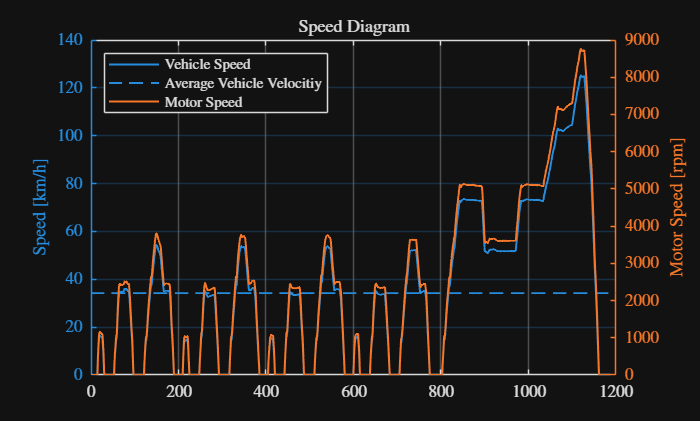

time = dataTable{:,1};              
vehicle_speed = dataTable{:,"VehicleSpeed[km/h]"};
motor_RPM = dataTable{:, "MotorSpeed[rpm]"};

figure
tiledlayout(1, 1)    

% Vehicle Speed, Mean-Vehicle Speed, Motor Speed
nexttile
yyaxis left
plot(time, vehicle_speed, 'LineWidth', 1.2)
hold on
plot(time, AVG_VELOCITY*ones(size(time)), 'LineWidth', 1.2)
grid on
ylabel('Speed [km/h]')
yyaxis right
plot(time, motor_RPM, 'LineWidth', 1.2)
grid on
ylabel('Motor Speed [rpm]');
title('Speed Diagram')
legend('Vehicle Speed', 'Average Vehicle Velocitiy', 'Motor Speed', 'Location','northwest')

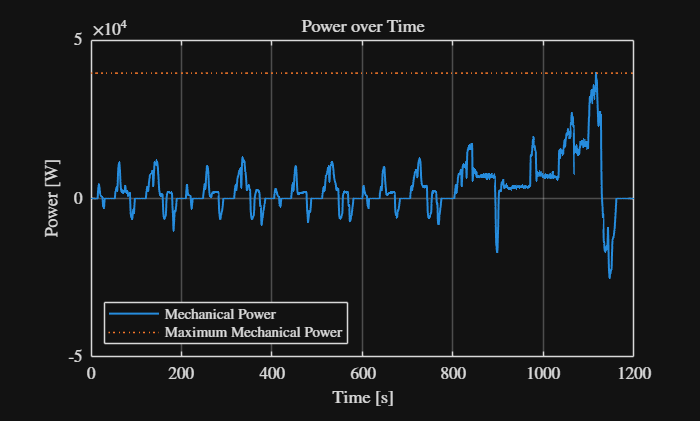

Powermech = dataTable{:,"P_mech[W]"};
Powermechmax = max(dataTable{:,"P_mech[W]"});

figure
tiledlayout(1, 1)    

% Mechanical Power
nexttile
plot(time, Powermech, 'LineWidth', 1.2)
line(time, Powermechmax*ones(size(time)), 'LineStyle',':')
grid on
xlabel('Time [s]')
ylabel('Power [W]')
title('Power over Time')
ylim([-5e4 5e4])
legend('Mechanical Power', 'Maximum Mechanical Power', 'Location','southwest')

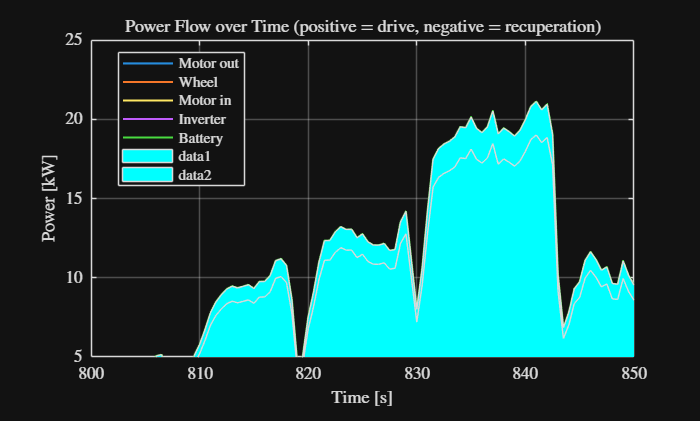

%% --- Setup ---
% Zeit und mechanische Motorleistung einlesen
time = dataTable{:, "sampling_time[s]"};                          % Zeitvektor
P_Motor_out = dataTable{:,"P_mech[W]"};              % mechanische Motorleistung

% Wirkungsgrade (prüfen, dass sie double sind)
eta_trans     = double(VEHICLE_PARAMETER.TRANSMISSION_EFFIENCY.data.value)/100;
eta_motor     = double(VEHICLE_PARAMETER.ENGINE_EFFIENCY.data.value)/100;
eta_inverter  = double(VEHICLE_PARAMETER.INVERTER_EFFIENCY.data.value)/100;
eta_battery   = double(VEHICLE_PARAMETER.BATTERY_EFFIENCY.data.value)/100;

%% --- Leistungsberechnung (Vorzeichenabhängig) ---
% Initialisierung
P_Wheel    = zeros(size(P_Motor_out));
P_Motor_in = zeros(size(P_Motor_out));
P_Inverter = zeros(size(P_Motor_out));
P_Battery  = zeros(size(P_Motor_out));

% Fahrphasen (positive Leistung)
idx_pos = P_Motor_out >= 0;
P_Wheel(idx_pos)    =  P_Motor_out(idx_pos) .* eta_trans;
P_Motor_in(idx_pos) =  P_Motor_out(idx_pos) ./ eta_motor;
P_Inverter(idx_pos) =  P_Motor_in(idx_pos) ./ eta_inverter;
P_Battery(idx_pos)  =  P_Inverter(idx_pos) ./ eta_battery;

% Rekuperationsphasen (negative Leistung)
idx_neg = P_Motor_out < 0;
P_Wheel(idx_neg)    =  P_Motor_out(idx_neg) ./ eta_trans;
P_Motor_in(idx_neg) =  P_Motor_out(idx_neg) .* eta_motor;
P_Inverter(idx_neg) =  P_Motor_in(idx_neg) .* eta_inverter;
P_Battery(idx_neg)  =  P_Inverter(idx_neg) .* eta_battery;

%% --- Plot ---
figure
tiledlayout(1, 1)
nexttile

plot(time, P_Motor_out/1000, 'LineWidth', 1.3, 'DisplayName','Motor out');
hold on
plot(time, P_Wheel/1000, 'LineWidth', 1.2, 'DisplayName','Wheel');
plot(time, P_Motor_in/1000, 'LineWidth', 1.2, 'DisplayName','Motor in');
plot(time, P_Inverter/1000, 'LineWidth', 1.2, 'DisplayName','Inverter');
plot(time, P_Battery/1000, 'LineWidth', 1.2, 'DisplayName','Battery');

fill([time, fliplr(time)], [P_Battery/1000 fliplr(P_Inverter/1000)], 'c');
% Fläche zwischen zwei kurven -> Fläche zw. bat und inv = inv loss
% chatgpt gibt gleiche antworten wie n zigeuner über politik

grid on
xlabel('Time [s]')
ylabel('Power [kW]')
title('Power Flow over Time (positive = drive, negative = recuperation)')
legend('Location','best')
ylim([5 25])
xlim([800 850])